# Pop and brood chamber

load('Data\BroodChamber.mat')

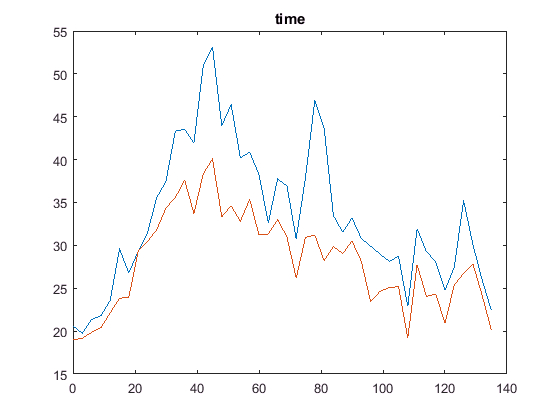



t0 = find(t==0); tend = find(t==135);
t1 = t(t0:tend);
C1 = BCsMean(t0:tend);
C2 = BClMean(t0:tend);
%Aer = M(1).SEM(t0:tend);
N = Popmean2(t0:tend);
%Ner = M(13).SEM(t0:tend);


% figure
% errorbar(N,C1,Aer,Aer,Ner,Ner,'o')
% hold on
% scatter(N,C1,[],t1,'filled')
% xlabel('No. of Ants')
% ylabel('functional Area [cm^2]')
% grid on
% c = colorbar;
% c.Label.String = 'Time in Days'; c.Label.FontSize = 11;

figure
plot(t1,C1,t1,C2)
title('time')

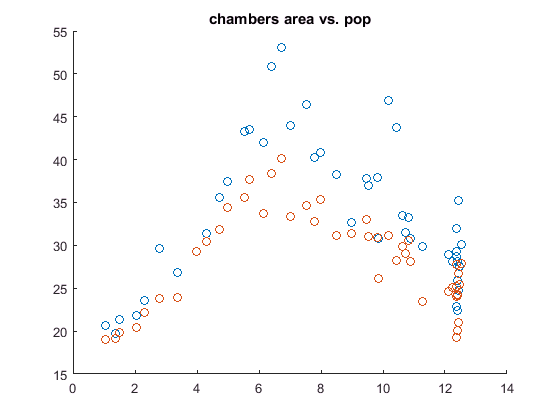


figure
scatter(N,C1)
hold on
scatter(N,C2)
title('chambers area vs. pop')

## Density

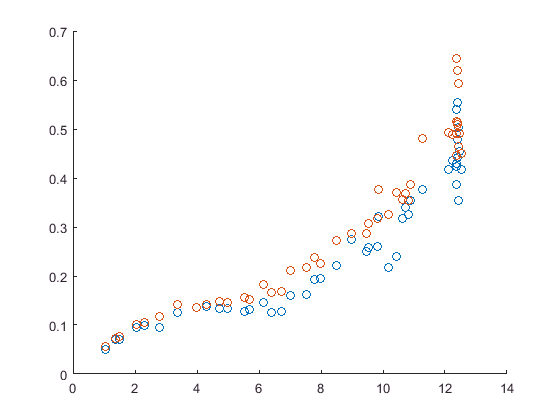

C1_d = N./C1;
C2_d = N./C2;

figure
scatter(N,C1_d)
hold on
scatter(N,C2_d)

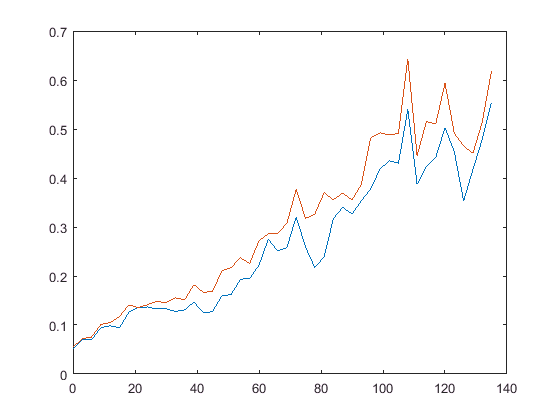


figure
plot(t1,C1_d,t1,C2_d)

Cross-Correlation

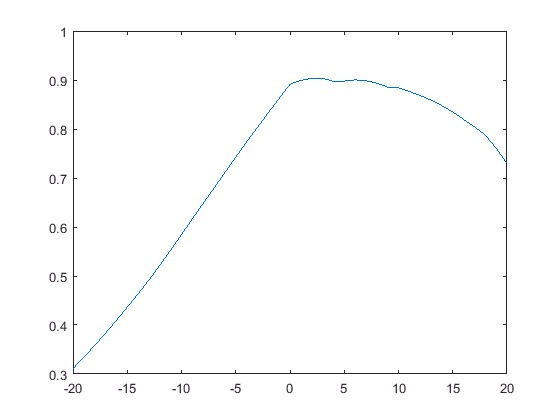

figure
[r,lags] = xcorr(N,C1,20,'coeff');
plot(lags,r)


% self-made X-corr,-> doesn't ignore zeros => not good
% maxlag = 20;
% L = -maxlag:1:maxlag;
% rs = zeros(numel(L),1);
% Ymaster = [zeros(maxlag,1);C1;zeros(maxlag,1)];
% for i=1:numel(L)
%     Y = Ymaster(maxlag-L(i)+1:maxlag-L(i)+numel(C1));
%     cr = corrcoef(N,Y);
%     rs(i) = cr(1,2);
% end
% 
% figure; plot(L,rs)

X-corr shows highest correlation between C1 (SumArea) and N between 0-8 (24 days) in future

Find correlation and density of the d(population) at that range

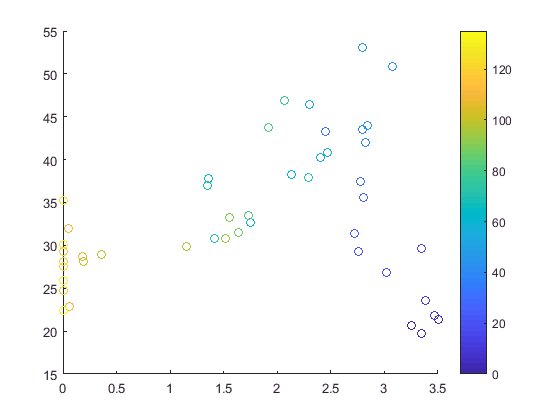

Nfuture = zeros(numel(N),1);
for i=1:numel(N)-8
%     if i+8>numel(N)
%         Nfuture(i)=N(end)-N(i);
%     else
        Nfuture(i)=N(i+8)-N(i);
%     end
end

figure
scatter(Nfuture,C1,[],t1)
colorbar

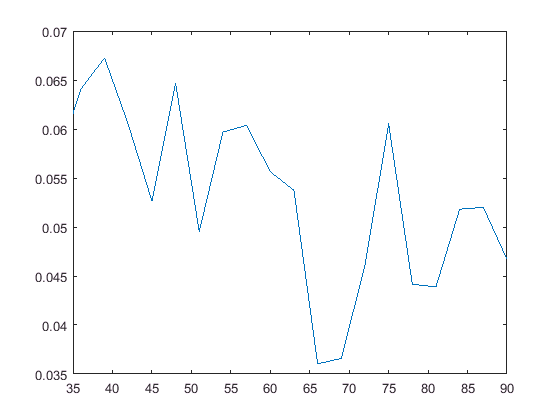


density = Nfuture./C1;
figure; plot(t1,density)
xlim([35 90])

# Conclusion: after high density of brood in beginning, manage to maintain constant density (orange line), (after population reaches plateau our way to estimate brood, no longer effective)

find relationship to combined density of workers (N) and brood (Nfuture)

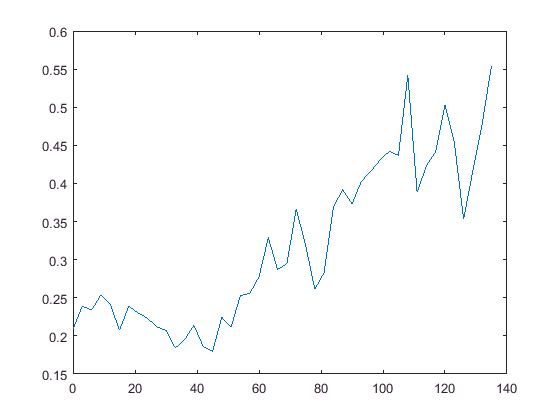

Nc = N+Nfuture;
density = Nc./C1;
figure; plot(t1,density)

Conclusion: no steady relationship

## Density vs. dAdt

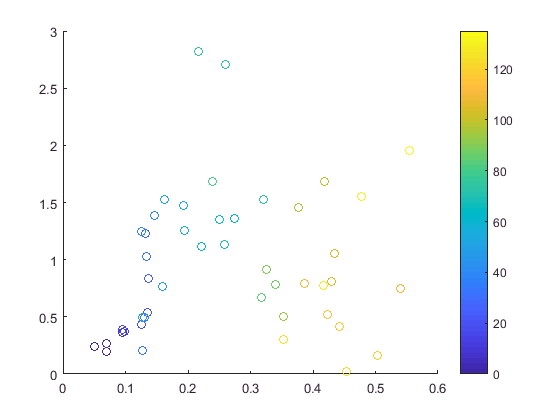

dAdt = gradient(A)./3;
figure
scatter(C1_d,dAdt,[],t1)
colorbar

Conclusion: no relationship between brood chamber size and fArea dig rate

=> look at x-corr

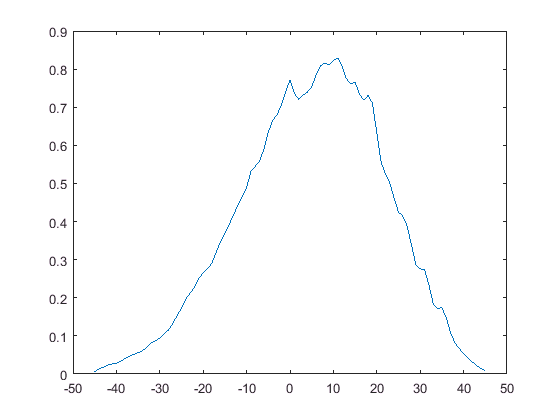

[r,lags] = xcorr(C1_d,dAdt,'coeff');
figure
plot(lags,r)

Conclusion: does not make sense, the x-corr result imply that the digging rate today is positively correlated with future density in chambers, if anything it should be correlated positively with the past and negatively with the future

## TRY to look at specific nests for 3 trends:

(1) density change in time by looking at chamber area vs. pop (just density can be misleading)

(2) chamber area vs. future pop (brood)

(3)  density vs. dAdt